## 📌 Challenge Code Template

clc; clear all; % Initialize variables and environment

- `clc`: Clears the MATLAB Command Window to ensure the output is clean and easy to read.

- `clear all`: Removes all variables from the Workspace memory to prevent conflicts with data from previous scripts.

 TEAM INFORMATION

Course: TC1003B

Project: Step 4 – Cost Analysis

 Team Members:

 1. Sebastián Noriega Olavarrieta – A00840922

 2. Sebastián Huerta González – A01724293

 3. Mássimo Brambilla Muela – A01178958

 4. Andres Sarmiento Felix – A00227878

Specific Comments on the Code

The MATLAB code begins by defining the outline points that represent the profile of the dog toy. 

Polynomial interpolation is then used to approximate the shape of the profile with smooth curves. 

After generating the final profile, the curve is rotated around the x-axis to create a 3D solid 

of revolution.

Numerical integration using the trapz function is applied to estimate the volume of the object. 

Finally, the density of the selected material is used to calculate the mass and estimate the 

production cost of the toy.

Variable Descriptions

x: Vector containing the x-coordinates of the outline points.

y: Vector containing the y-coordinates of the outline points representing the radius of the object.

x_final: Vector of refined x-values used to generate a smoother curve.

y_final: Radius values obtained from the polynomial interpolation of the outline points.

theta: Angular vector used to rotate the profile around the x-axis.

X, Y, Z: Matrices used to generate the 3D model of the solid of revolution.

volume: Volume of the object calculated using numerical integration.

density: Density of the selected material (natural rubber).

mass_g: Mass of the object in grams.

mass_kg: Mass of the object in kilograms.

material_cost_mxn: Estimated cost of the raw material.

total_cost_mxn: Total estimated production cost per unit.

x1: Vector containing the x-coordinates of the upper outline points.

y1: Vector containing the y-coordinates of the upper outline points representing the radius of the object.

x2: Vector containing the x-coordinates of the lower outline points.

y2: Vector containing the y-coordinates of the lower outline points representing the inner profile of the object.

p1: Cubic polynomial coefficients used to approximate the upper outline.

p2: Cubic polynomial coefficients used to approximate the lower outline.

x1_plot: Vector of refined x-values used to generate a smoother curve for the upper outline.

y1_plot: Radius values obtained from evaluating the polynomial p1.

x2_plot: Vector of refined x-values used to generate a smoother curve for the lower outline.

y2_plot: Radius values obtained from evaluating the polynomial p2.

Detailed Explanation of the Steps Followed in the Solution point 10

1. The outline points of the dog toy were defined using vectors of x and y coordinates.

2. Polynomial interpolation was applied to approximate the profile of the object.

3. A smoother curve was generated to represent the final profile of the toy.

4. The curve was rotated around the x-axis to generate a 3D solid of revolution.

5. The volume of the object was calculated using numerical integration with the trapz function.

6. The mass was calculated using the density of the selected material.

7. The material cost was estimated using the price of natural rubber per kilogram.

8. Additional production costs were added to estimate the total manufacturing cost per unit.

Detailed Explanation of the Steps Followed in the Solution point 1 - 3

1. The outline points of the dog toy were defined using vectors of x and y coordinates.

The vectors x and y contain the coordinates of the key points that describe the 2D profile of the toy.

The x-values represent the horizontal positions along the shape, while the y-values represent the radius or height of the profile at each point.

This step defines the silhouette of the object before creating the 3D model.

2. Polynomial interpolation was applied to approximate the profile of the object.

The outline was divided into two sections: the upper outline and the lower outline.

A cubic polynomial was fitted to each section using polyfit, and then evaluated with polyval.

This made it possible to transform the original discrete points into smooth curves that better represent the shape of the toy.

3. A smoother curve was generated to represent the final profile of the toy.

The vectors x1_plot, y1_plot, x2_plot, and y2_plot were combined into x_final and y_final.

These final vectors form a continuous and smoother 2D profile of the object.

This profile is the one later used to generate the solid of revolution and calculate the volume.

Code Contribution

Outline points definition – Sebastián Noriega

Polynomial interpolation – Andres Sarmiento

3D model generation – Massimo Brambilla

Volume calculation – Sebastián Huerta

Cost calculations – Sebastián Huerta

Polynomial - Andres Sarmiento

Final vectors - Sebastian Noriega

# **1️⃣ Define outline points**

x = [-2.66,-2.29,-1.62,-0.39,1.11,1.66,2,2.07,-0.39,-0.81,-0.76,-0.45,-0.1,-0.11]; 
y = [0.19,1.41,2.15,2.55,2.15,1.48,1,0.14,0.8,0.62,0.28,0.08,0.29,0.62]; 

`x = [...]`**, **`y = [...]`: Defines two vectors, **x** and **y**, representing a set of points in 2D space.

- **x**: Represents the horizontal positions along the profile.

- **y**: Represents the heights associated with each x-coordinate.

📌 This defines the **2D outline** of the object before it is rotated. Think of it as the "silhouette" of the shape you are about to create.

# **2️⃣ Get the polynomial for each section **

% ----- Section 1: Upper outline -----
% Define the points that describe the upper part of the toy silhouette.
% x1 represents the horizontal positions of the outline.
% y1 represents the radius of the object at each x-position.

x1 = [-2.66, -2.29, -1.62, -0.39, 1.11, 1.66, 2, 2.07];
y1 = [ 0.19,  1.41,  2.15,  2.55, 2.15, 1.48, 1, 0.14];

% Fit a cubic polynomial that approximates the shape of the upper outline.
% polyfit finds the polynomial coefficients that best fit the given points.
p1 = polyfit(x1, y1, 3);                 % Cubic polynomial fit

% Generate a smoother set of x-values to draw a continuous curve.
x1_plot = linspace(min(x1), max(x1), 200);

% Evaluate the polynomial at the new x-values to obtain the smooth curve.
y1_plot = polyval(p1, x1_plot);


% ----- Section 2: Lower outline -----
% Define the points that describe the lower inner section of the toy.
% This region represents the cavity or internal shape of the toy.

x2 = [-0.39, -0.81, -0.76, -0.45, -0.1, -0.11];
y2 = [ 0.8,   0.62,  0.28,  0.08,  0.29,  0.62];

% Fit another cubic polynomial for the lower section of the profile.
% This creates a smooth curve that approximates the lower points.
p2 = polyfit(x2, y2, 3);                 % Cubic polynomial fit

% Generate a refined x vector for plotting the lower outline smoothly.
x2_plot = linspace(min(x2), max(x2), 200);

% Evaluate the polynomial to obtain the smooth lower outline curve.
y2_plot = polyval(p2, x2_plot);

# **3️⃣ Create final x & y vectors for the outline**

x_final = [x1_plot, x2_plot];
y_final = [y1_plot, y2_plot];

`x_final`** / **`y_final`: Merges all the x and y values generated in each section.

- `x_final`: Combines all the horizontal segments into a single, continuous coordinate vector.

- `y_final`: Combines all the calculated polynomial heights into a single vector.

This step creates a **smooth, continuous 2D profile**. By joining the segments  you ensure there are no gaps in the "skin" of your object before the rotation begins.

Imagine your `x_final` and `y_final` vectors as a piece of wire bent into a specific shape. Currently, it only exists in a flat 2D world.

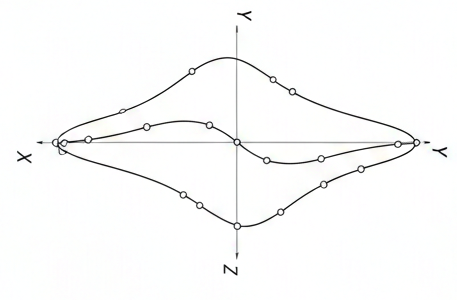

# **4️⃣ 3D Rotation**

## Understanding the "Revolution" Loop

In MATLAB, a **meshgrid** is essentially a coordinate system that tells the program where every single point of a surface is located in 3D space. The `for` loop in your script acts as a "3D printer" that builds this mesh one slice at a time.

nPoints = 100; % Number of rotation sections
theta = linspace(0, 2*pi, nPoints+1); % 0 a 360 degrees

Here is the translation for the 3D rotation parameters:

`nPoints = 100;` → Defines how many points will be used in the rotation (higher number = smoother surface).

`linspace(0, 2*pi, nPoints);`Creates 100 equally spaced values from 0° to 360° (expressed in **radians**).

📌 Each point on the profile will be rotated through these angles to generate the 3D shape.

# **5️⃣ Set the 3D Matrices to create de suface**

X = zeros(nPoints+1, length(x_final));
Y = zeros(nPoints+1, length(x_final));
Z = zeros(nPoints+1, length(x_final));

`X = zeros(...)`**, **`Y = zeros(...)`**, **`Z = zeros(...)`: Creates matrices filled with **zeros** of size (100, number of profile points).

- These matrices will store the **X, Y, and Z coordinates** of the rotated solid.

📌 This is where we will save the 3D points after the profile has been rotated.

# **6️⃣ Apply Cilindric Rotation**

for i = 1:length(x_final)
    X(:, i) = x_final(i); 
    Y(:, i) = y_final(i) * cos(theta); 
    Z(:, i) = y_final(i) * sin(theta); 
end

**The Loop Logic: Slice by Slice**

The loop `for i = 1:length(x_final)` takes every single point on that wire and swings it around the X-axis in a full circle.

- `X(:, i) = x_final(i);`This fixes the "station" along the horizontal axis. For a specific point on the profile, its X-position stays the same as it rotates.

- `Y(:, i) = y_final(i) * cos(theta);`

- `Z(:, i) = y_final(i) * sin(theta);`This is the trigonometry that creates the circle. Since `theta` goes from 0 to 2π, these lines calculate the coordinates for 100 points around the axis.

By the time the loop finishes, you have three large matrices:

- **Matrix X:** The "length" or positions of each circular slice.

- **Matrix Y:** The "width" of the rotation.

- **Matrix Z:** The "depth" of the rotation.

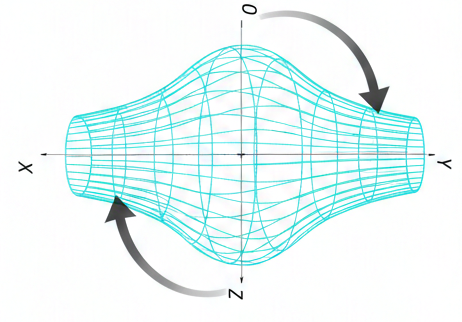

# **7️⃣ Set the graphic window**

figure;
hold on;
axis equal;
grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Solid of revolution');

`figure;` → Opens a new window for the graphic.

`hold on;` → Keeps all plotted objects in the same figure (so the new surface doesn't erase previous elements).

`axis equal;` → Ensures correct proportions. This prevents the object from looking "squashed" or "stretched" by making the units equal on all axes.

`grid on;` → Adds a coordinate grid to the background.

`xlabel`**, **`ylabel`**, **`zlabel` → Axis labels (identifying which direction is X, Y, and Z).

`title` → Adds a title to the top of the plot.

**📌 The graphic window is configured to show the 3D model.**

# **8️⃣ Plot 3D model**

surf(X, Y, Z, 'FaceColor', 'cyan', 'EdgeColor', 'none', 'FaceAlpha', 0.6);


- `FaceColor = 'cyan'` → Uses a cyan color for the surface.

- `EdgeColor = 'none'` → Disables the drawing of the mesh grid lines (edges), making the object look smoother.

- `FaceAlpha = 0.6` → Sets the transparency to 60%. This allows you to see "through" the object slightly.

📌 When you call `surf(X, Y, Z)`, MATLAB connects the dots between these points to create a "skin" over the skeleton.

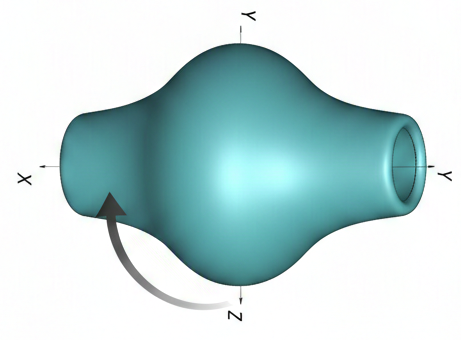

# **9️⃣ Improve lighting**

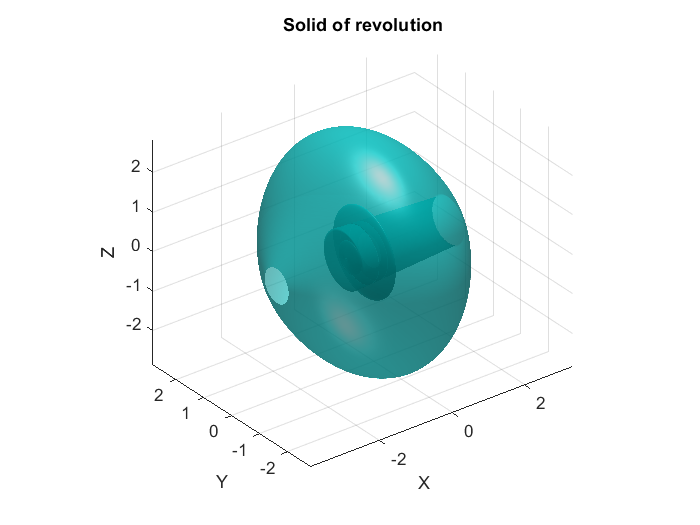

camlight('headlight'); 
lighting phong; 
view(3); 

`camlight('headlight');` → Adds a light source to enhance the 3D effect. It works like a flashlight attached to the "camera" or the viewer's eyes.

`lighting phong;` → Uses the **Phong lighting model**, which provides a more realistic appearance. It calculates how light reflects off the surface, creating highlights and shadows that give the object a sense of volume.

`view(3);` → Automatically adjusts the camera to the default 3D perspective. Without this, MATLAB might display the plot from a flat, top-down (2D) view.

# **🔟 Cost analysis**

%% ---- Section 5: Volume Calculation ----
% We calculate the volume of the solid using the washer method
% V = pi ∫ r(x)^2 dx

volume = pi * trapz(x_final, y_final.^2);

fprintf('Volume of the dog toy: %.4f cm^3\n', volume);

Volume of the dog toy: 67.2976 cm^3



%% ---- Section 6: Material Properties ----
% Selected material: Natural Rubber
% Reason: Natural rubber is commonly used in dog chew toys because it is flexible,
% durable, and safe for pets.

density = 1.10; % g/cm^3

% Mass calculation
mass_g = density * volume;
mass_kg = mass_g / 1000;

fprintf('Mass of the dog toy: %.4f g\n', mass_g);

Mass of the dog toy: 74.0274 g


fprintf('Mass of the dog toy: %.6f kg\n', mass_kg);

Mass of the dog toy: 0.074027 kg



%% ---- Section 7: Material Cost (MXN) ----
% Average price of natural rubber raw material in Mexico

price_per_kg_mxn = 43.66; % MXN/kg

material_cost_mxn = mass_kg * price_per_kg_mxn;

fprintf('Material cost: $%.2f MXN\n', material_cost_mxn);

Material cost: $3.23 MXN



%% ---- Section 8: Production Costs ----
% Estimated manufacturing costs per unit

labor_cost_mxn = 10;      % manufacturing labor
energy_cost_mxn = 5;      % electricity / machine usage
finishing_cost_mxn = 4;   % trimming / quality check
packaging_cost_mxn = 6;   % packaging materials

total_cost_mxn = material_cost_mxn + labor_cost_mxn + energy_cost_mxn + finishing_cost_mxn + packaging_cost_mxn;

fprintf('Labor cost: $%.2f MXN\n', labor_cost_mxn);

Labor cost: $10.00 MXN


fprintf('Energy cost: $%.2f MXN\n', energy_cost_mxn);

Energy cost: $5.00 MXN


fprintf('Finishing cost: $%.2f MXN\n', finishing_cost_mxn);

Finishing cost: $4.00 MXN


fprintf('Packaging cost: $%.2f MXN\n', packaging_cost_mxn);

Packaging cost: $6.00 MXN


fprintf('Total production cost: $%.2f MXN\n', total_cost_mxn);

Total production cost: $28.23 MXN
